# Pre set up

clear all;
close all;
clc;

# Load data

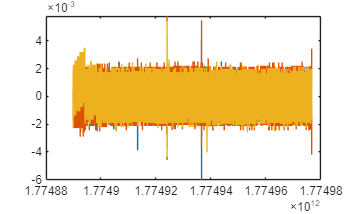

data = load("sensorlog_angvel_20260330_165739.mat");

table = data.sensorlog_angvel_20260330_165739;
table_angular_velocity = [table.X, table.Y, table.Z];

%% Visualization pre elaboration
figure(1);
plot(table.timestamp, table_angular_velocity);

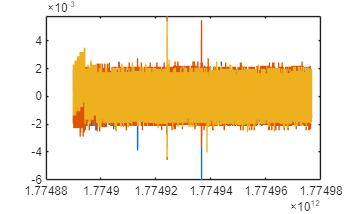

%% Filtering
% Crop initial data and last data
index = 6000; % [100 hz so 6000 is first 60 seconds]
start_index = index;
end_index = height(table) - index;

% Create a new trimmed table
table_trimmed = table(start_index:end_index, :);
table_angular_velocity_trimmed = [table_trimmed.X, table_trimmed.Y, table_trimmed.Z];

% Plot the new data
figure(2);
plot(table_trimmed.timestamp, table_angular_velocity_trimmed);

## Model:


$$\Omega \left(t\right)=\Omega_{\textrm{ideal}} \left(t\right)+\textrm{ARW}\left(t\right)+\textrm{RRW}\left(t\right)+\textrm{BI}\left(t\right)$$


Where:

- $\Omega_{\textrm{ideal}}$ is the ideal real value

- $\textrm{ARW}$ is the Angle Random Walk

- $\textrm{RRW}$ is the Rate Random Walk

- $\textrm{BI}$ is the BIas Instability

## Allan Variance Calculation

We consider only the x axis for simplicity

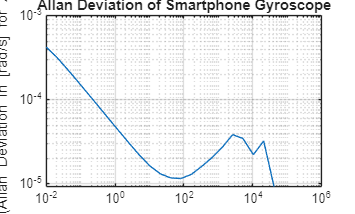

Fs = 100; % [Hz], frequency of matlab mobile sampling

omega = table_angular_velocity_trimmed(:, 1);

[alan_var, tau] = allanvar(omega, 'octave', Fs);
allan_dev = sqrt(alan_var);

%% Plot
figure(1);
loglog(tau, allan_dev); 
grid on;
title('Allan Deviation of Smartphone Gyroscope');
xlabel('\tau (Averaging Time in [s])');
ylabel('\sigma(\tau) (Allan Deviation in [rad/s] for X-axis)');

## Angle random walk

We can model:


$$\sigma {\;}^2 \left(\tau \;\right)=\frac{N^2 }{\tau \;}$$


Therefore in a log-log plot with $\sigma \left(\tau \right)$versus $\tau \;$we would have a line with a slope of $-\frac{1}{2}$, namely:


$$\log \left(\sigma \;\right)=-\frac{1}{2}\log \left(\tau \;\right)+\log \left(N\right)$$


So the value of $N$ can be read at $\tau =1$

slope = -1/2;
log_tau = log10(tau);
log_allan_dev = log10(allan_dev);
dlog_allan_dev = diff(log_allan_dev) ./ diff(log_tau);
[~, i] = min(abs(dlog_allan_dev - slope));

% Find the intercept of the line.
b = log_allan_dev(i) - slope*log_tau(i);

% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 4.8055e-05

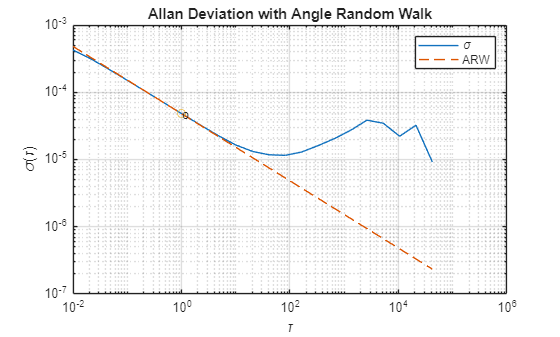



% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);

figure(2)
loglog(tau, allan_dev, tau, lineN, '--', tauN, N, 'o')
title('Allan Deviation with Angle Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', 'ARW')
text(tauN, N, 'o')
grid on

## Rate random walk

We can model:


$$\sigma {\;}^2 \left(\tau \;\right)=\frac{K^2 \tau \;}{3}\;$$


Therefore in a log-log plot with $\sigma \left(\tau \right)$versus $\tau \;$we would have a line with a slope of $\frac{1}{2}$, meaning :


$$\log \left(\sigma \;\right)=\frac{1}{2}\log \left(\tau \;\right)+\log \left(K\right)-\frac{1}{2}\log \left(3\right)$$


We can determine the value of $K$at $\tau =3$because clearly the above equation simplifies to


$$\log \left(\sigma \;\right)=\log \left(K\;\right)$$


% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 1/2;
logtau = log10(tau);
log_allan_dev = log10(allan_dev);
dlog_allan_dev = diff(log_allan_dev) ./ diff(log_tau);
[~, i] = min(abs(dlog_allan_dev - slope));

% Find the intercept of the line.
b = log_allan_dev(i) - slope*log_tau(i);

% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
K = 10^logK

K = 1.2999e-06

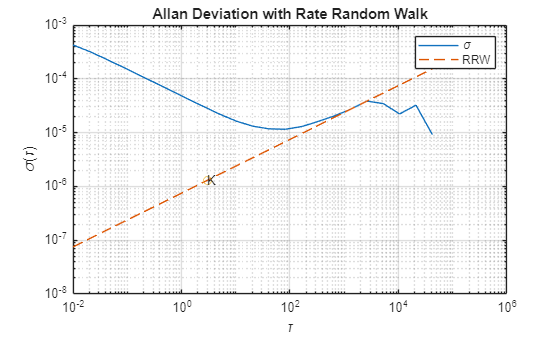


% Plot the results.
tauK = 3;
lineK = K .* sqrt(tau/3);

figure(3);
loglog(tau, allan_dev, tau, lineK, '--', tauK, K, 'o')
title('Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', 'RRW')
text(tauK, K, 'K')
grid on

## Bias Instability

We can model:


$$\sigma^2 \left(\tau \;\right)={\frac{2B}{\pi \;}}^2 \ln \left(2\right)$$


Therefore in a log-log plot with $\sigma \left(\tau \right)$versus $\tau \;$we would have a line with a slope of $0$, meaning:


$$\log \left(\sigma \;\right)=\frac{1}{2}\log \left({\frac{2B}{\pi \;}}^2 \ln \left(2\right)\right)$$


The value of $B$ can be read off of this line with a scaling of $\sqrt{\;\left(2\frac{\ln \left(2\right)}{\pi \;}\right)}\approx 0\ldotp 664$

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0;
log_tau = log10(tau);
log_allan_dev = log10(allan_dev);
dlog_allan_dev = diff(log_allan_dev) ./ diff(log_tau);
[~, i] = min(abs(dlog_allan_dev - slope));

% Find the y-intercept of the line.
b = log_allan_dev(i) - slope*log_tau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 1.7690e-05

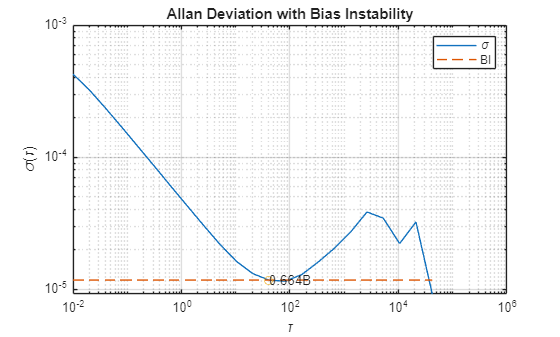


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure(4);
loglog(tau, allan_dev, tau, lineB, '--', tauB, scfB*B, 'o')
title('Allan Deviation with Bias Instability')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', 'BI')
text(tauB, scfB*B, '0.664B')
grid on

## Gyroscope simulation

% Set the gyroscope parameters to the noise parameters determined
% above. Use single-sided noise to match the parameter scaling and 500
% poles for the bias instability model to match the hardware output.
numpoles = 500;
gyro = gyroparams(  'NoiseDensity', N, ...
                    'RandomWalk', K, ...
                    'BiasInstability', B, ...
                    'NoiseType', 'single-sided', ...
                    'BiasInstabilityCoefficients', fractalcoef(numpoles));

% Create the IMU Sensor object
imu = imuSensor('accel-gyro', 'SampleRate', Fs);
imu.Gyroscope = gyro;

% Run the simulation 
% vectors of zeros are the real values
numSamples = size(omega, 1);
accel_ground_truth = zeros(numSamples, 3); % m/s^2
gyro_ground_truth  = zeros(numSamples, 3); % rad/s

% Generate simulated readings
[~, gyro_readings] = imu(accel_ground_truth, gyro_ground_truth);


## Plot comparison simulated vs real

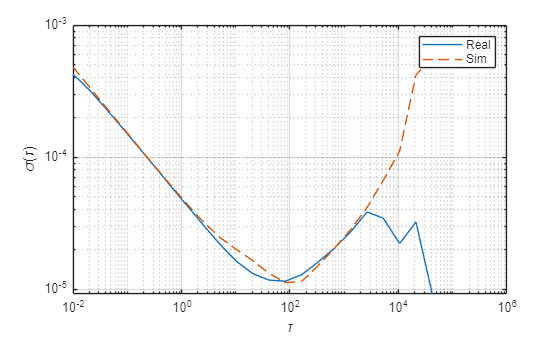

omega_sim = gyro_readings(:, 1);
[allan_var_sim, tau_sim] = allanvar(omega_sim, 'octave', Fs);

allan_dev_sim = sqrt(allan_var_sim);
allan_dev_sim = mean(allan_dev_sim, 2); % Use the mean of the simulations.

figure(5);
loglog(tau, allan_dev, tau_sim, allan_dev_sim, '--')
xlabel('\tau');
ylabel('\sigma(\tau)')
legend('Real', 'Sim')
grid on